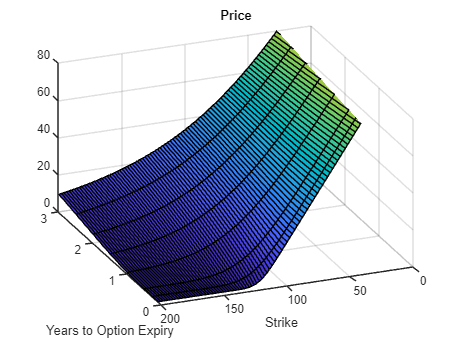

%heston model vanilla option: 

%parameters for estimation:

AssetPrice = 120;
Rate = 0.05; %RFR
DividendYield = 0.05;
OptSpec = 'call';

%Option positioning
V0 = 0.04;
ThetaV = 0.2;
Kappa = 1.0;
SigmaV = 0.2;
RhoSV = -0.7;

%computation for single strike (Numerial integration)

Settle = datetime(2020,6,29);
Maturity = datemnth(Settle, 12*[1/12 0.25 (0.5:0.5:3)]');
Times = yearfrac(Settle, Maturity);
Strike = (2:2:200)';

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield, ...
    'ExpandOutput', true);

[X,Y] = meshgrid(Times,Strike);

figure;
surf(X,Y,Call);
title('Price');
xlabel('Years to Option Expiry');
ylabel('Strike');
view(-112,34);
xlim([0 Times(end)]);
zlim([0 80]);

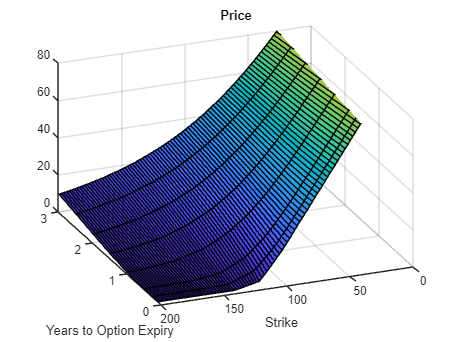

%%%%%% FFT Method

Call = optByHestonFFT(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield, ...
    'ExpandOutput', true);

[X,Y] = meshgrid(Times,Strike);

figure;
surf(X,Y,Call);
title('Price');
xlabel('Years to Option Expiry');
ylabel('Strike');
view(-112,34);
xlim([0 Times(end)]);
zlim([0 80]);